# **Investigating Network Behavior**

You've seen how to use classification scores and occlusion maps to gain insights into a network's predictions. In this reading, you'll dig deeper and investigate network behavior, sorted both by classification result (correct or incorrect prediction) and by class. 

Comparing your incorrect and correct predictions or looking at specific classes gives you more detailed information about how your model is behaving.

## **Classify the Fastener Test Images**

Click the control and select the location of the Test images for the Fastener classification dataset.

filenameTest = "/Users/vysakhpr/Documents/Coursera/Deep Learning for Computer Vision/Data/MathWorks Created/Fasteners/Classification/Test";

Create an image datastore and augmented image datastore.

imdsTest = imageDatastore(filenameTest, "IncludeSubfolders", true, ...
    "LabelSource", "foldernames");
augTest = augmentedImageDatastore([224, 224], imdsTest);

Load the model and extract the list of classes.

load fastenerResnet18Classifier.mat net
classes = string(net.Layers(end).Classes);

Because our class labels have underscores, and MATLAB figures interpret underscores as subscripts, the axes of our bar chart won't look as expected. Address this by adding a backslash to the string of classes.

classesString = replace(string(classes), "_", "\_");

Classify the images in the test set. Return both the predicted class labels and scores.

`scores` is a matrix of confidence scores where each row corresponds to an image in the test set, and each column corresponds to a class.

[testPreds, scores] = classify(net, augTest);

## **Splitting Your Data by Prediction Result**

Previously, you compared `testPreds` to the true labels to calculate accuracy. Now, you'll use that comparison to create two new datastores: one for the correctly classified images and another for misclassified images.

`correctLabel` has a value of 1 (true) when the prediction is correct and 0 (false) when it is incorrect.

correctLabel = testPreds == imdsTest.Labels;

Use the `subset` function to create datastores for the correct and misclassified images.

correctIMDS = subset(imdsTest, correctLabel);
wrongIMDS = subset(imdsTest, ~correctLabel);

## Examine the Incorrect Images

Now that you have a datastore for incorrect images, you can examine them more easily and look for patterns. Run this section to view confidence scores and occlusion maps.

Select a new image from the wrong predictions by adjusting the value of `imgIdx` below:

numWrong = nnz(~correctLabel); % for use by the control
imgIdx = 3;
img = readimage(wrongIMDS, imgIdx);
% resize to the size of the network
img = imresize(img, [224 224]);
% classify the image and return the score
[pred, score] = classify(net, img);

View a bar plot of the confidence scores. 

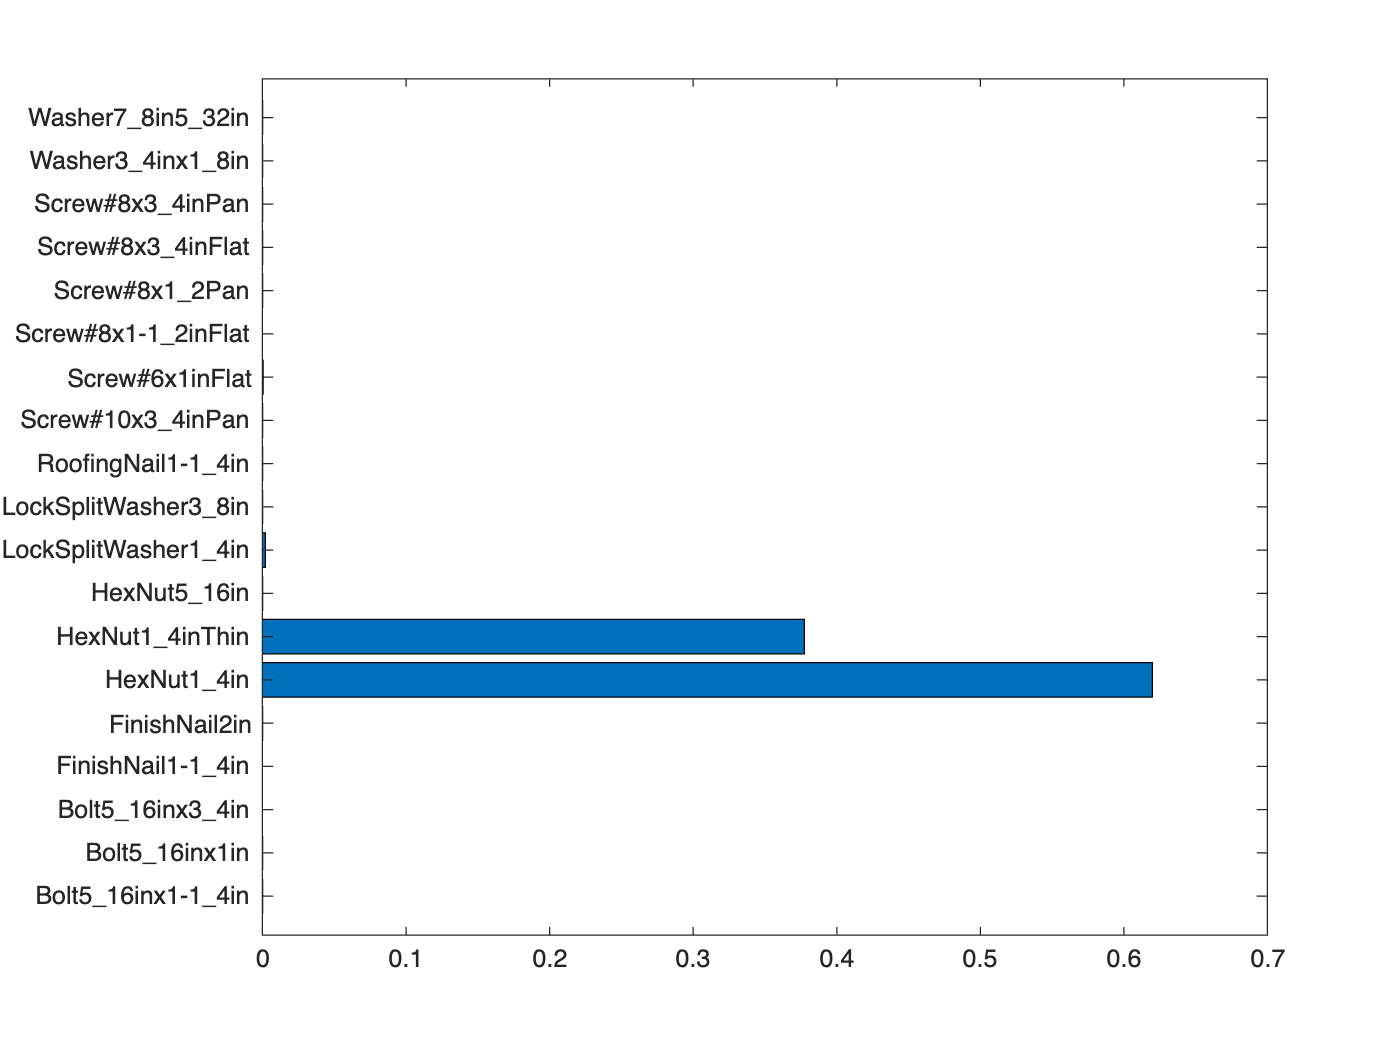

barh(classesString, score);

View the occlusion maps. This code creates occlusion maps for the incorrectly classified image using both the incorrect prediction and the correct label.

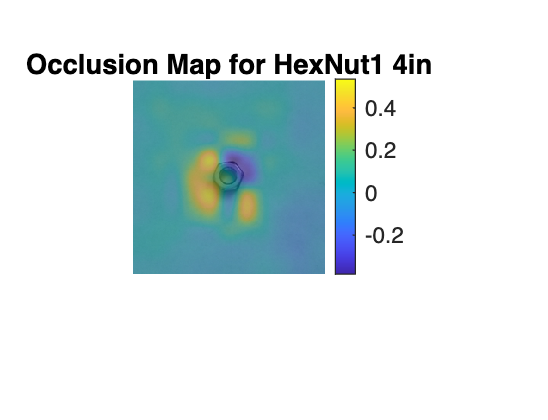

mapWrongClass = occlusionSensitivity(net, img, pred);
mapCorrectClass = occlusionSensitivity(net, img, wrongIMDS.Labels(imgIdx));

% Visualize occlusion map for the predicted class
imshow(img)
hold on
imagesc(mapWrongClass, "AlphaData", 0.5)
hold off
title("Occlusion Map for " + replace(string(pred), "_", " "))
set(0,'DefaultTextInterpreter','none');
colorbar

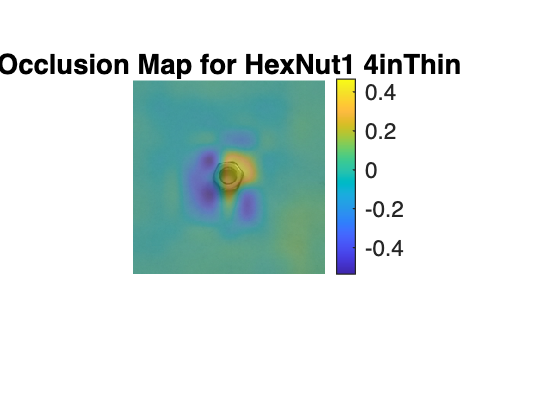


% Visualize the occlusion map for the correct class
imshow(img)
hold on
imagesc(mapCorrectClass, "AlphaData",0.5)
hold off
title("Occlusion Map for " + replace(string(wrongIMDS.Labels(imgIdx)), "_", " "))
colorbar
set(gca,'TickLabelInterpreter','none');

### Interpreting the Occlusion Maps

Use the colorbar to interpret occlusion maps. Positive values indicate regions that are evidence for the specified class. Negative values are regions that provide evidence for another class. Because the above images were misclassified, creating an occlusion map for the correct class (which wasn't predicted) will show a lot of negative values.

### Investigate Some Correct Predictions

Perform a similar analysis for the correct images in `correctIMDS`. Because these are correct predictions, you only need to create a single occlusion map with the correct label.

imgIdx = 3;
img = readimage(correctIMDS, imgIdx);
% resize to the size of the network
img = imresize(img, [224 224]);
% classify the image and return the score
[pred, score] = classify(net, img);

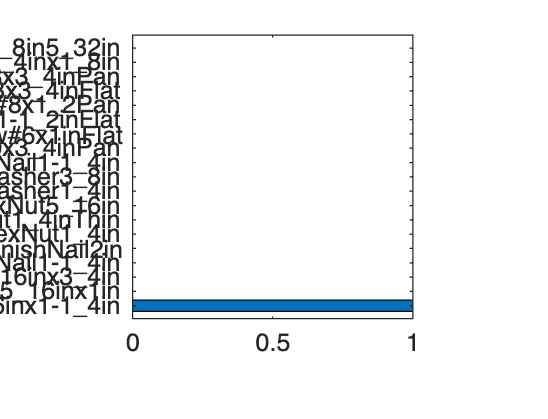

barh(classesString, score);

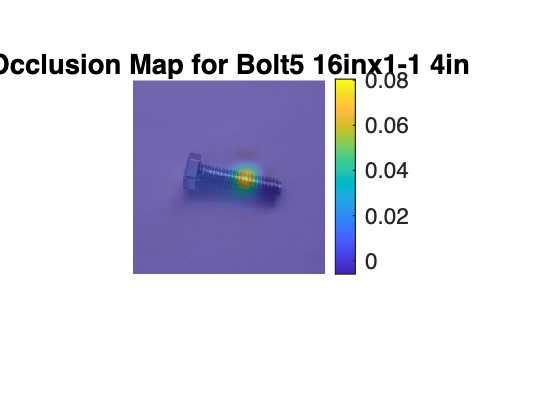

mapClass = occlusionSensitivity(net, img, correctIMDS.Labels(imgIdx));

% Visualize occlusion map for the predicted class
imshow(img)
hold on
imagesc(mapClass, "AlphaData", 0.5)
hold off
title("Occlusion Map for " + replace(string(pred), "_", " "))
set(0,'DefaultTextInterpreter','none');
colorbar

## **Investigate Results by Class**

This model did not misclassify many images. However, in the future you may encounter models that perform well on some classes but poorly on others.

When that happens, you may want to investigate the results of a specific class to find possible reasons the model performed poorly. You can do this by creating a datastore with only images of a single class.

Use the drop-down to select a class to investigate.

class = classes(1);

Use the `subset` function to create a new datastore containing only the specified class.

isClass = class == imdsTest.Labels;
classIMDS = subset(imdsTest, isClass);

Select an image from the class using the control below.

numClass = nnz(isClass);
imgIdx = 1;
img = readimage(classIMDS, imgIdx);

Resize and classify the image.

img = imresize(img, [224 224]);
[pred, score] = classify(net, img);

View the results:

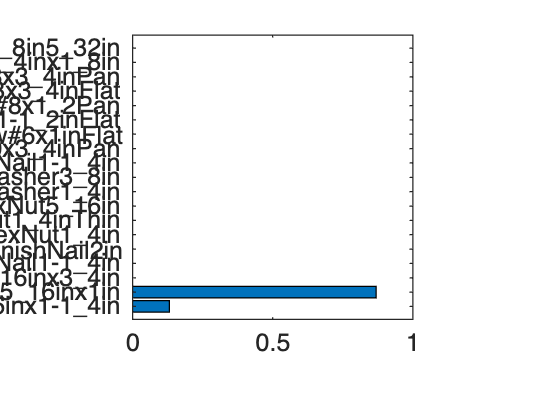

barh(classesString, score);

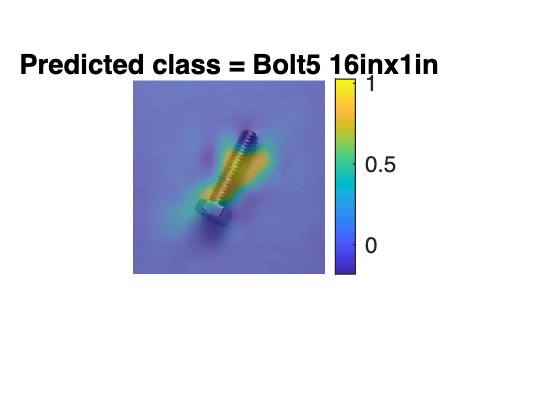

map = occlusionSensitivity(net, img, pred);
imshow(img)
hold on
imagesc(map, "AlphaData",0.5)
hold off
colorbar
title("Predicted class = " + string(replace(string(pred), "_", " ")))
set(gca,'TickLabelInterpreter','none');

Was the prediction correct? 

If you have a class with many incorrect predictions, this is a good approach to explore those predictions and decide what actions you might take to improve the results. 

## Concluding Remarks

Confidence scores and occlusion maps are powerful tools for learning more about your network's behavior and troubleshooting your deep learning models. It can also be useful to separate your data by incorrect/correct predictions and by class.

For other approaches to visualizing network behavior, refer to [the documentation](https://www.mathworks.com/help/deeplearning/ug/deep-learning-visualization-methods.html) on deep learning visualization methods.

*Copyright 2024 The MathWorks, Inc.*